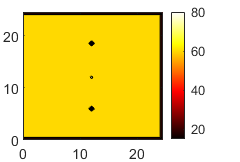

% Lets code the heat diffusion PDE in 2D for laptop cooling 
% u(xx) + u(yy) = u(t)

H = 0.06; % Heat transfer coefficients [W/cm^2.K]
alpha = 89.2E-2; % Thermal diffusivity of Silicon @ 300K [cm^2/s]
K = 1.48; % Thermal conductivity of Silicon @ 300K [W/cm.K]
h = 0.5; % Space step
k = 0.125; % Time step
r = k*alpha/(h^2);
t = k:k:20;
x = 0:h:24.5; % Width of domain (laptop)
y = 0:h:24.5; % Height of domain (laptop)
Tgen = 80; % CPU chip temperature
Tinf = 10; % Cooling liquid temperature
Tcool = 15; % Cooling fan temperature 

% Populate initial stencil
grid_points = zeros(length(y),length(x));
% Dirichlet & initial conditions
[m, n] = size(grid_points);
for i = 1:m
    for j = 1:n
        grid_points(i, j) = 60;
        grid_points(1, j) = 35;
        grid_points(i, n) = 35;
        grid_points(m, j) = 35;
        grid_points(int16(m/2), int16(n/2)) = Tgen;
        grid_points(int16(m/4), int16(n/2)) = Tcool;
        grid_points(int16(3*m/4), int16(n/2)) = Tcool;
    end
end

% Initial plot ;)

[X, Y] = meshgrid(x, y);
contourf(X, Y, grid_points)
colormap("hot")
colorbar
drawnow;


% Code for Dirichlet at 3 boundaries and Neumann at 1
eva = []; % Points to evaluate
g = grid_points; % copy the stencil
for i = 2:m-1
    for j = 2:n-1
        eva = [eva, [i; j]]; % MatLab does not support tuples, hence a way around this is coded
    end
end
% Neumann points lets apply this to the left surface
neumann = [];
for i = 1:m
    for j = 1:n
        if (i ~= 1) && (i ~= m) && (j == 1) % Apply Neumann conditions at the left surface
            neumann = [neumann, [i; j]];
        end
    end
end
non_nue = length(eva);
eva = [eva, neumann]; % Include the Neumann points into the points to evaluate

% Iterate through time (time for a pain in the ass)
for l = 1:length(t)
    k = length(eva);
    M = zeros(k,k);
    B = zeros(k);

    % Populate B
    a = 1;
    for i = 2:m-1
        for j = 2:n-1
            B(a) = r*(g(i+1,j) + g(i-1,j) + g(i,j+1) + g(i,j-1)) + (2 - 4*r)*(g(i,j));
            a = a + 1;
        end
    end

    coeff = [];
    b = 1;
    for i = 2:m-1
        for j = 2:n-1
            coeff = [coeff; [i i+1 i-1 i i ; j j j j+1 j-1]];
            if i-1 == 1
                B(b) = B(b) + r*(g(i-1,j));
            end
            if i+1 == m
                B(b) = B(b) + r*(g(i+1,j));
            end
            if j+1 == n
                B(b) = B(b) + r*(g(i,j+1));
            end
            b = b + 1;
        end
    end

    % Populate M
    count = 0;
    for i = 1:non_nue
        for j = 1:k
            coe = coeff(i+count:i+count+1, :);
            if if_in(eva(:, j), coe) == 1
                M(i,j) = -1*r;
            end
        end
        count = count + 1;
    end

    % Lets solve for the Nuemann points (More ass pain)
    c = non_nue+1;
    for i = 1:length(neumann)
        s = neumann(1, i);
        p = neumann(2, i);
        B(c) = r*(g(s+1,p) + g(s-1,p) + 2*(g(s,p+1)) + (4*h*H/K)*Tinf) + (2 - 4*r - (2*h*H/K)*r)*(g(s,p));
        nuenue = [s;p+1];
        for j = 1:k
            if if_in(eva(:, j), nuenue) == 1
                M(c,j) = -2*r;
            end
            if if_in([s+1;p], neumann) == 1
                M(c, non_nue+(i+1)) = -1*r;
            end
            if if_in([s-1;p], neumann) == 1
                M(c, non_nue+(i-1)) = -1*r;
            end
        end
        c = c + 1;
    end

    % Diagonalise M for non_nuemann points
    for i = 1:non_nue
        M(i ,i) = (2 + 4*r);
    end
    % Diagonalise M for nuemann points
    for i = non_nue+1:k
        M(i, i) = (2 + 4*r + (2*h*H/K)*r);
    end

    % Update B again based of dirichlet conditions for a more generalized
    % approach
    d = non_nue+1;
    for i = 2:m-1
        if i-1 == 1
            B(d) = B(d) + r*(g(i-1,1));
        end
        if i+1 == m
            B(d) = B(d) + r*(g(i+1,1));
        end
        d = d + 1;
    end

    % Solve and update the point values
    sol = M\B;
    for i = 1:length(eva)
        w = eva(1, i);
        q = eva(2, i);
        g(w, q) = sol(i);
    end

    g(int16(m/2), int16(n/2)) = 0.25*t(l) + Tgen; % Reset the midpoint (chip) temperature to Tgen (constant heat gen) OR Linearly increasing heat generation
    g(int16(m/4), int16(n/2)) = Tcool; % Reset fan temperature model constant heat sink
    g(int16(3*m/4), int16(n/2)) = Tcool; % Reset fan temperature model constant heat sink
    grid_new = g;

    % Lets plot this shit, fuckin hell that was long
    [X, Y] = meshgrid(x, y);
    contourf(X, Y, grid_new)
    colormap("hot")
    colorbar
    drawnow;
end



function M = if_in(x ,v)
    N = [];
    for i = 1:length(v(1,:))
        if (x(1) == v(1,i)) && (x(2) == v(2,i))
            N = [N, 1];
        else
            N = [N, 0];
        end
    end
    M = max(N);
end
% Function that acts as the if in command in Python
